%% where are the data?
clc; clear; close all;
pixelsize=107; %nm.
exposure=0.05; %second
dimension=3;
path='E:\Data\DNA-PAINT(Live-cell)\SPT_tracking\Basal_tracking\210610_live_DNA-PAINT_tracking4000\2\';

if ~exist('ImageFile','var')|| isempty(ImageFile)
    [userfilein, userdirin]=uigetfile({
         '*.tif','PSD image file (*.tif)';...
        '*.*','All Files (*.*)'},'Select PSD image file to process',...
        path);
    ImageFile=fullfile(userdirin,userfilein);
else
    if ~exist(ImageFile,'file')
        fprintf('File not found: %s\n',ImageFile);
        return;
    else [userdirin,~,~]=fileparts(ImageFile);
        userdirin=strcat(userdirin,'\');
    end
end
if ~exist('TrackingFile','var')|| isempty(TrackingFile)
    [userfilein, userdirin]=uigetfile({
         '*.txt','Result tracking file (*.txt)';...
        '*.*','All Files (*.*)'},'Select result tracking file to process',...
        path);
    TrackingFile=fullfile(userdirin,userfilein);
else
    if ~exist(TrackingFile,'file')
        fprintf('File not found: %s\n',TrackingFile);
        return;
    else [userdirin,~,~]=fileparts(TrackingFile);
        userdirin=strcat(userdirin,'\');
    end
end
if ~exist('Diffusion_with_ID','var')|| isempty(Diffusion_with_ID)
    [userfilein, userdirin]=uigetfile({
         '*.mat','diffusion_coefficient file (*.mat)';...
        '*.*','All Files (*.*)'},'Select diffusion_coefficient file to process',...
        path);
    Diffusion_with_ID=fullfile(userdirin,userfilein);
else
    if ~exist(Diffusion_with_ID,'file')
        fprintf('File not found: %s\n',Diffusion_with_ID);
        return;
    else [userdirin,~,~]=fileparts(Diffusion_with_ID);
        userdirin=strcat(userdirin,'\');
    end
end

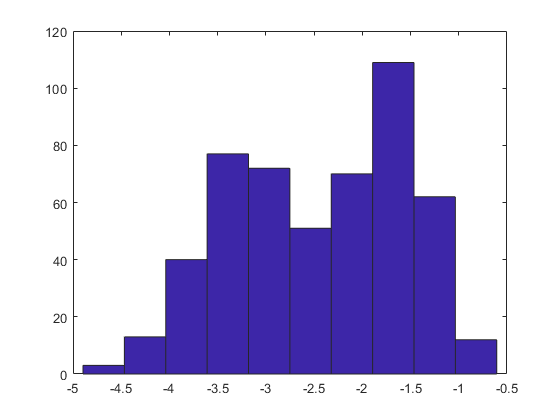

%% load the data
Homer=imread(ImageFile);
Traj=textread( TrackingFile);
load(Diffusion_with_ID);
log_diffcoeff=[log10(Dif_track_W_ID(:,1)) Dif_track_W_ID(:,2)];
% following lines are for sorting trajectories of
% which the diffusion coefficient can be
% calculated.
uniqueID=unique(Dif_track_W_ID(:,2));
for i=1:length(Traj)
    if ismember(Traj(i,5),uniqueID)==0
        Traj(i,:)=zeros(1,5);
    else
    end  
end
clear i;
Traj_filtered=Traj(any(Traj,2),:);

ID=Traj_filtered(:,5);
x1=Traj_filtered(:,1);
x=x1/pixelsize;
y1=Traj_filtered(:,2);
y=y1/pixelsize;
z1=Traj_filtered(:,3);
t=Traj_filtered(:,4);
tracking_result=[ID t x y z1];

hist(log_diffcoeff(:,1)); % use this to roughly see

% the range of diffusion coefficient.

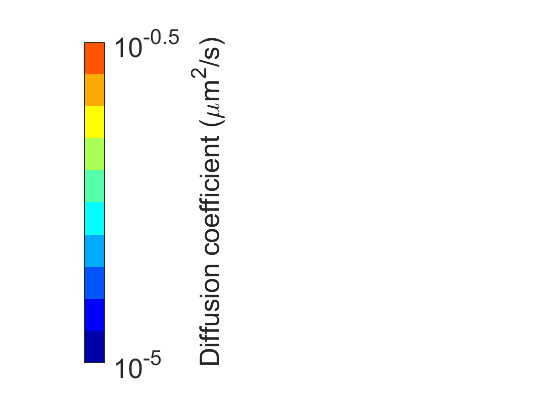

%% creating color code for diffusion
Diffmin=-5;
Diffmax=-0.5;
Diffstep=10;
figure;
ax = axes;
cmap=colormap(jet(Diffstep));
c=colorbar('Ticks',[0,1],'TickLabels',{['10^' '{' num2str(Diffmin) '}'], ['10^' '{' num2str(Diffmax) '}']},'FontSize',20,'Location','west');
c.Label.String='Diffusion coefficient (\mum^2/s)';
ax.Visible = 'off';


Diff_range=linspace(Diffmin+abs(Diffmin+Diffmax)/(2*Diffstep),Diffmax-abs(Diffmin+Diffmax)/(2*Diffstep),Diffstep);

ColorCode=zeros(length(Dif_track_W_ID),1);
for i=1:length(Dif_track_W_ID)
    [val, ColorCode(i)]=min(abs(Diff_range-log_diffcoeff(i,1)));
end
clear i;

%% creating cells for trajectories
[Uid,~,ix] = unique(tracking_result(:,1));
tally = accumarray(ix, ones(size(ix)));
C = mat2cell(tracking_result, tally, [5]); % note that the column of each cell -> 1: ID, 2: frame number 3: x in px, 4: y in px, 5: z in nm.

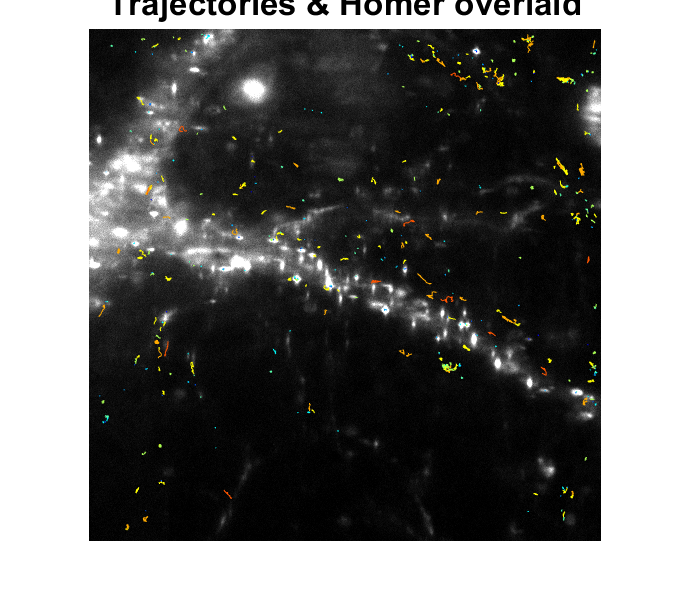

%% showing 1 image and the trajectoris
figure;
contrast_min=220;
contrast_max=4140;
imshow(Homer, [contrast_min contrast_max]);
%colorMap=[zeros(16384,1) linspace(0,1,16384)' zeros(16384,1)]; % R, G, B
%colormap(colorMap);
hold on
for k = 1:size(C,1)
    plot(C{k}(:,3), C{k}(:,4),'Color',cmap(ColorCode(k),:))

end
hold off;
title('Trajectories & Homer overlaid','FontSize',25);

## showing the image and the trajectoris

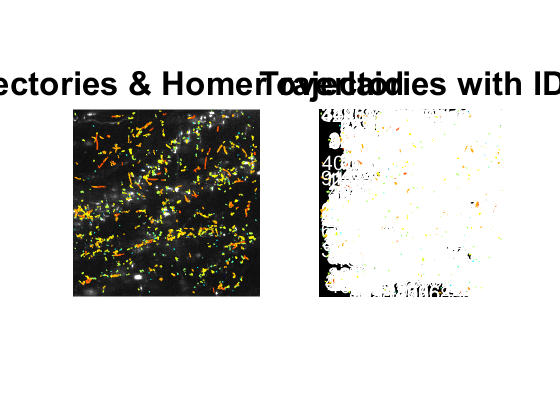

contrast_min2=0;
contrast_max2=5190;
figure;
ax(1)=subplot(1,2,1);
imshow(Homer, [contrast_min2 contrast_max2]);
%colorMap=[zeros(16384,1) linspace(0,1,16384)' zeros(16384,1)]; % R, G, B
%colormap(colorMap);
hold on
for k = 1:size(C,1)
    plot(C{k}(:,3), C{k}(:,4),'Color',cmap(ColorCode(k),:))

end
hold off;
title('Trajectories & Homer overlaid','FontSize',25);

BGimage=zeros(512,512);
%figure; % trajectory only with the ID.
ax(2)=subplot(1,2,2);
imshow(BGimage);
hold on;
for k = 1:size(C,1)
    plot(C{k}(:,3), C{k}(:,4),'Color',cmap(ColorCode(k),:))
    h=text(C{k}(1,3),C{k}(1,4),num2str(C{k}(1,1)),'Color','white','FontSize',15);
    set(h, 'Clipping','on');
end
hold off;
linkaxes(ax, 'xy');
title('Trajectories with ID','FontSize',25);


clear k;

%% make msd curve for each trajectory
MSD=cell(length(C),1);
for i=1:length(MSD);
    ID=C{i}(:,1);
    time=exposure*(C{i}(:,2)-C{i}(1,2));
    xy_pos=C{i}(:,3:4);
    z_pos=C{i}(:,5);
    position=[xy_pos*pixelsize/1000 z_pos/1000]; % in micron
    position(:,1)=position(:,1)-position(1,1);
    position(:,2)=position(:,2)-position(1,2);
    position(:,3)=position(:,3)-position(1,3);
    msd=((position(:,1)-position(1,1)).^2+(position(:,2)-position(1,2)).^2+(position(:,3)-position(1,3)).^2);
    MSD{i}=[ID time msd];
    clear ID time xy_pos z_pos position msd
end
clear i;


%% calculate instantaneous diffusion coefficient by interpolation -> derivative take absolute value of slope.
t_step=0.01;
MSD_diff=cell(length(MSD),1);
for i=1:length(MSD); 
    t_q=0:t_step:MSD{i}(length(MSD{i}),2); % make grid for interpolation.
    msd_q=interp1(MSD{i}(:,2),MSD{i}(:,3),t_q); %1D interpolation
    msd_s=smooth(msd_q); % smoothing
    deriv_msd_s=diff(msd_s)/t_step;
    D_inst=deriv_msd_s/(2*dimension);
    D_inst=[D_inst; D_inst(end)];
    D_inst=abs(D_inst);
    D_inst_s=smooth(D_inst); % smoothing
    MSD_diff{i}=[MSD{i}(1,1)*ones(length(t_q),1) t_q' msd_s D_inst_s msd_q' D_inst];
    clear t_q msd_q msd_s deriv_msd_s D_inst D_inst_s
end

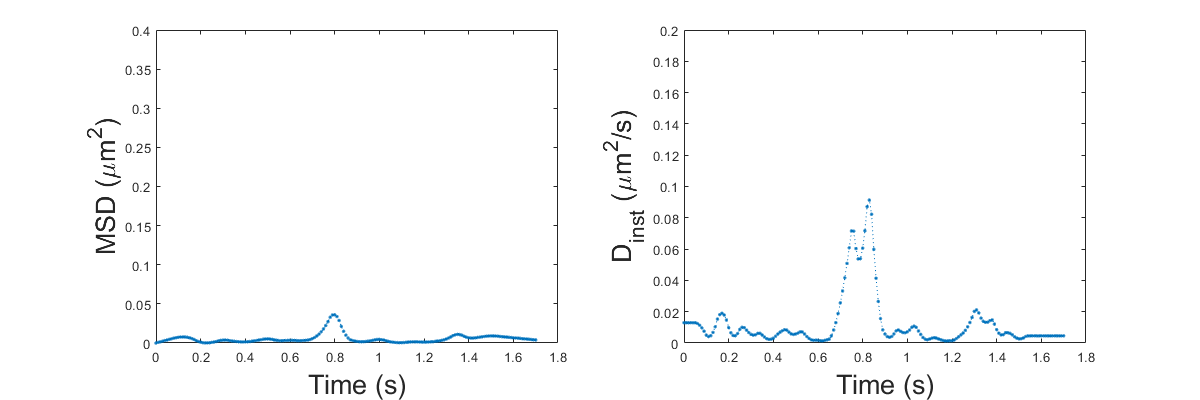

%% plot MSD and DiffCoeff_Inst curve by interpol-smooth-derivative

max_j=length(Uid);
j=101;

index=find(Uid==j);

figure;
subplot(1,2,1);
plot(MSD_diff{index}(:,2),MSD_diff{index}(:,3),':.');% smoothed
%plot(MSD_diff{index}(:,2),MSD_diff{index}(:,5),':.'); % not smoothed
ax=gca;
ax.YAxis.FontSize=15;
ax.XAxis.FontSize=15;
xlabel('Time (s)','FontSize',20);
ylabel('MSD (\mum^2)','FontSize',20);
ylim([0 0.4]);
subplot(1,2,2);
plot(MSD_diff{index}(:,2),MSD_diff{index}(:,4),':.'); % smoothed
%plot(MSD_diff{index}(:,2),MSD_diff{index}(:,6),':.');% not smoothed
ax=gca;
ax.YAxis.FontSize=15;
ax.XAxis.FontSize=15;
xlabel('Time (s)','FontSize',20);
ylabel('D_{inst} (\mum^2/s)','FontSize',20);
ylim([0 0.2]);
set(gcf,'Position',[100 100 1200 400]);

%suptitle(['Trajectory:' num2str(j)]);